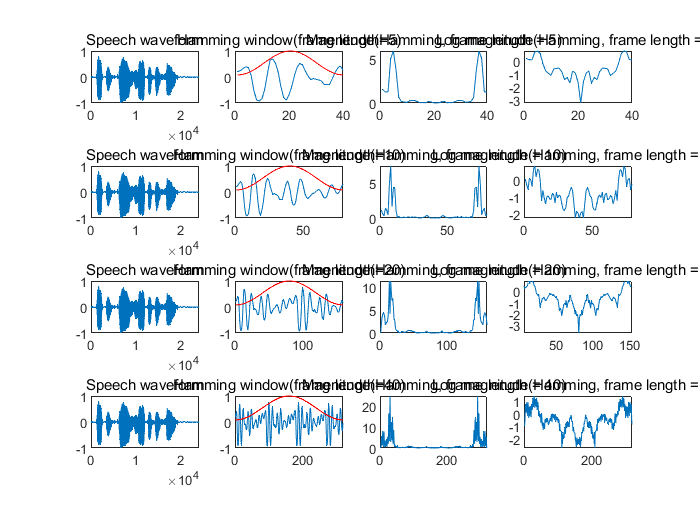

% Prompt: Write a MATLAB program to perform (and compare the results of) multiple short-time analyses of a section of speech using multiple window lengths.
% Your program should accept the following inputs:
% 1. the number of short-time spectral analyses to be compared
% 2. the speech filename
% 3. the starting sample within the speech array for analysis of the short-time spectrum
% 4. the frame lengths in msec for each of the multiple analyses.
% For each of the spectral analyses you will have to convert from the input frame length in msec to the frame length in samples, based on the sampling rate of the sampled speech signal being analyzed. You should do the short-time analyses using both a Hamming window and a rectangular window so as to be able to contrast the results for these two windows.
% Your program output should be a plot with the multiple spectral analyses when using a Hamming window, and a separate plot with the multiple spectral analyses using a rectangular window. Each plot should include four sub-plots with the following:
% 1. the speech waveform for the file being analyzed
% 2. the waveforms of the speech segments being analyzed, showing the window superimposed over the waveform
% 3. the magnitude of the short-time transforms, using a different color for each of the analyses
% 4. the log magnitude (in dB) of the short-time transforms, again using a different color for each of the analyses

% Clear the workspace and the command window
clear;
clc;

% Define the number of short-time spectral analyses to be compared
num_analyses = 4;

% Define the speech filename
filename = 's5.wav';

% Load the speech signal
[speech, fs] = audioread(filename);

% Define the starting sample within the speech array for analysis of the short-time spectrum
start_sample = 7000;

% Define the frame lengths in msec for each of the multiple analyses
frame_lengths = zeros(1, num_analyses);
for i = 1:num_analyses
    frame_lengths(i) = input(sprintf('Enter the frame length in msec for analysis %d: ', i));
end
% Perform short-time spectral analyses using a Hamming window
figure;
for i = 1:num_analyses
    % Convert frame length in msec to frame length in samples
    frame_length_samples = round(frame_lengths(i) * fs / 1000);
    
    % Define the Hamming window
    hamming_window = hamming(frame_length_samples);
    
    % Extract the speech segment for analysis
    speech_segment = speech(start_sample:start_sample+frame_length_samples-1);
    
    % Apply the Hamming window to the speech segment
    hamming_windowed_segment = speech_segment .* hamming_window;
    
    % Compute the short-time Fourier transform using the Hamming window
    stft_hamming = abs(fft(hamming_windowed_segment));
    
    % Plot the speech waveform
    subplot(num_analyses, 4, (i-1)*4+1);
    plot(speech);
    title('Speech waveform');
    
    % Plot the speech segment with window superimposed
    subplot(num_analyses, 4, (i-1)*4+2);
    plot(speech_segment);
    hold on;
    plot(hamming_window, 'r');
    title(sprintf('Hamming window(frame length=%d)', frame_lengths(i)));
    
    % Plot the magnitude of the short-time transform
    subplot(num_analyses, 4, (i-1)*4+3);
    plot(stft_hamming);
    title(sprintf('Magnitude(Hamming, frame length = %d)', frame_lengths(i)));
    
    % Plot the log magnitude of the short-time transform
    subplot(num_analyses, 4, (i-1)*4+4);
    plot(log10(stft_hamming));
    title(sprintf('Log magnitude(Hamming, frame length = %d)', frame_lengths(i)));
end

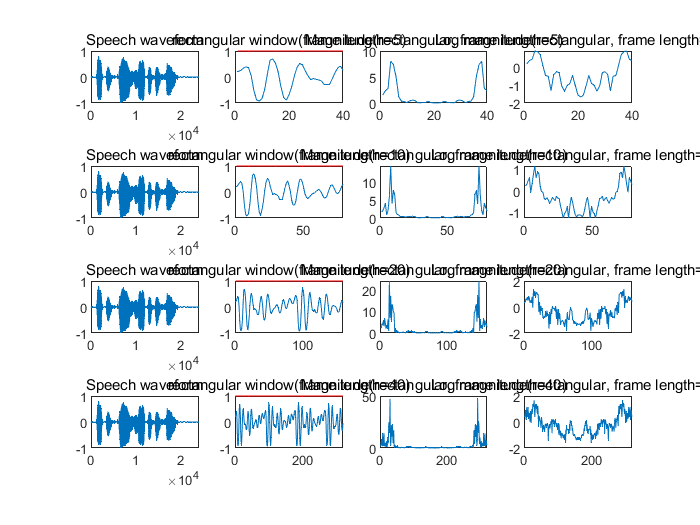


% Perform short-time spectral analyses using a rectangular window
figure;
for i = 1:num_analyses
    % Convert frame length in msec to frame length in samples
    frame_length_samples = round(frame_lengths(i) * fs / 1000);
    
    % Define the rectangular window
    rectangular_window = rectwin(frame_length_samples);
    
    % Extract the speech segment for analysis
    speech_segment = speech(start_sample:start_sample+frame_length_samples-1);
    
    % Apply the rectangular window to the speech segment
    rectangular_windowed_segment = speech_segment .* rectangular_window;
    
    % Compute the short-time Fourier transform using the rectangular window
    stft_rectangular = abs(fft(rectangular_windowed_segment));
    
    % Plot the speech waveform
    subplot(num_analyses, 4, (i-1)*4+1);
    plot(speech);
    title('Speech waveform');
    
    % Plot the speech segment with window superimposed
    subplot(num_analyses, 4, (i-1)*4+2);
    plot(speech_segment);
    hold on;
    plot(rectangular_window, 'r');
    title(sprintf('rectangular window(frame length=%d)', frame_lengths(i)));
    
    % Plot the magnitude of the short-time transform
    subplot(num_analyses, 4, (i-1)*4+3);
    plot(stft_rectangular);
    title(sprintf('Magnitude(rectangular, frame length=%d)', frame_lengths(i)));
    
    % Plot the log magnitude of the short-time transform
    subplot(num_analyses, 4, (i-1)*4+4);
    plot(log10(stft_rectangular));
    title(sprintf('Log magnitude(rectangular, frame length=%d)', frame_lengths(i)));
end